# Vẽ dữ liệu DSP

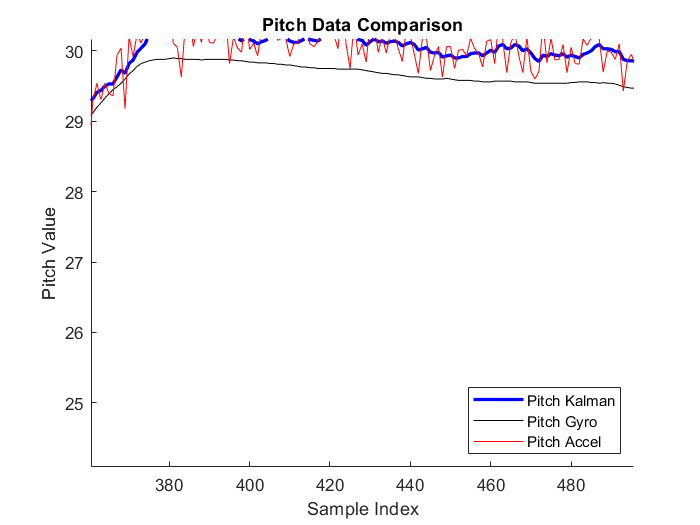

% Đọc dữ liệu từ các cột cụ thể trong tệp Excel
 Pitch_Kalman = xlsread('D:\BAI_TAP\Word\DSP_DATA\DATA_DSP.xlsx',1,'A2:A905');
 Pitch_Gyro = xlsread('D:\BAI_TAP\Word\DSP_DATA\DATA_DSP.xlsx',1,'B2:B905');
 Pitch_Accel = xlsread('D:\BAI_TAP\Word\DSP_DATA\DATA_DSP.xlsx',1,'C2:C905');
 % Lưu các biến vào file .mat
%save('Pitch_Data.mat', 'Pitch_Kalman', 'Pitch_Gyro', 'Pitch_Accel');

% Vẽ đồ thị
figure;  % Tạo một cửa sổ đồ thị mới
hold on; % Giữ các đồ thị hiện tại để vẽ thêm

% Vẽ đồ thị cho từng dữ liệu
plot(Pitch_Kalman, 'b', 'LineWidth', 2, 'DisplayName', 'Pitch_Kalman');  % Màu đen cho Pitch_Kalman ('k')
plot(Pitch_Gyro, 'k', 'DisplayName', 'Pitch_Gyro');      % Màu xanh biển cho Pitch_Gyro ('b')
plot(Pitch_Accel, 'r', 'DisplayName', 'Pitch_Accel');    % Màu đỏ cho Pitch_Accel ('r')

% Thêm tiêu đề, nhãn trục và chú thích
title('Pitch Data Comparison');
xlabel('Sample Index');
ylabel('Pitch Value');
legend('Pitch Kalman', 'Pitch Gyro', 'Pitch Accel','Location', 'southeast');

hold off;  % Thả đồ thị để không vẽ thêm nữa